clear
A1 = [0 1 0; 0 0 1;-0.2 0.6 0.3];
B1 = [1.8;-1.1;0.7];
C1 = [1 0 0];
D1 = 0.4;

%Stable system ?

abs(eig(A1))

ans =     0.7450
    0.3414
    0.7864



%transfer function

sys1 = ss(A1,B1,C1,D1,-1);

H = tf(sys1)


H =
 
  0.4 z^3 + 1.68 z^2 - 1.88 z + 0.03
  ----------------------------------
     z^3 - 0.3 z^2 - 0.6 z + 0.2
 
Sample time: unspecified
Discrete-time transfer function.




% H2 norm

pl = dlyap(A1,B1*B1')

pl =     6.2653   -4.1697    3.2522
   -4.1697    3.0253   -2.1897
    3.2522   -2.1897    1.8153



H2sys1 = sqrt(D1^2 + C1*pl*C1')

H2sys1 = 2.5348


%impulse response

[Y,T] = impulse(sys1)

Y =     0.4000
    1.8000
   -1.1000
    0.7000
   -0.8100
    0.3970
   -0.5069
    0.2481
   -0.3091
    0.1575


T =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


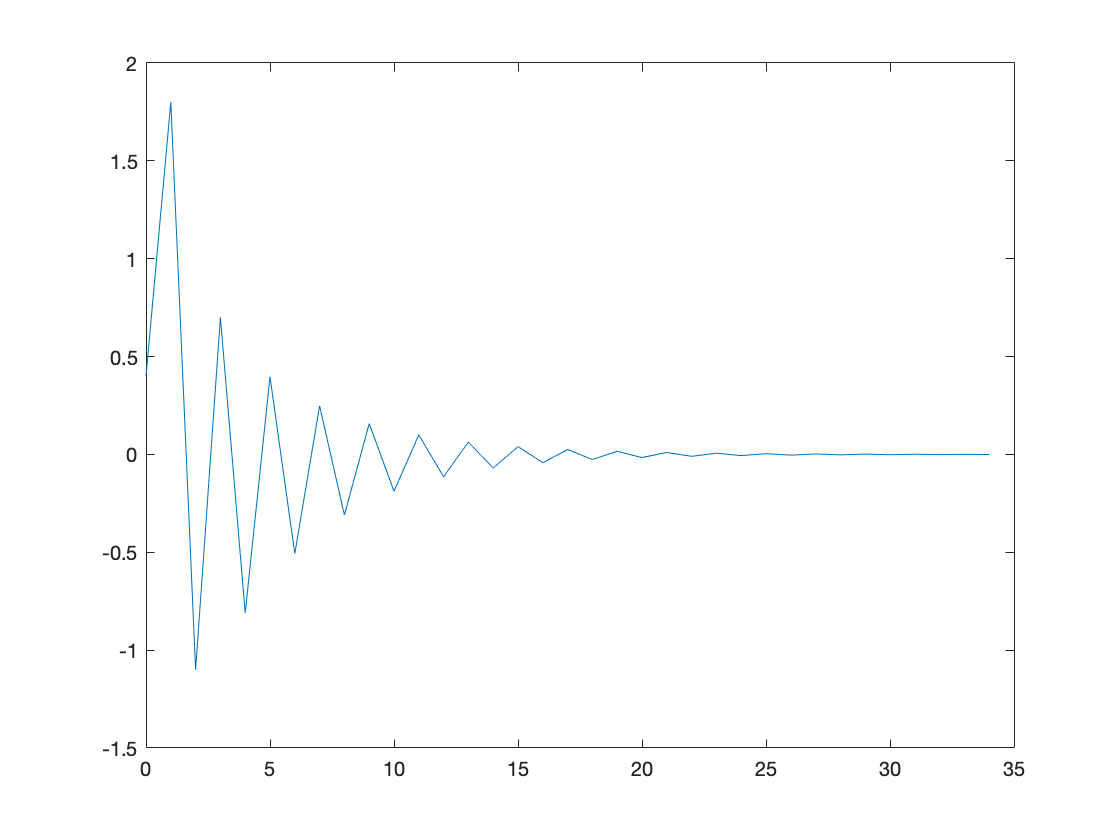

plot(T,Y)

max(abs(Y))

ans = 1.8000



%2 

A2 = [1.1 0.3; -0.4 0.5];
B2 = [-1.2;0.3]

B2 =    -1.2000
    0.3000


C2 = [0.3 0.4]

C2 =     0.3000    0.4000


D2 = -0.2

D2 = -0.2000


%Stable system ?

abs(eig(A2))

ans =     0.8185
    0.8185



%transfer function

sys2 = ss(A2,B2,C2,D2,-1);

G = tf(sys2)


G =
 
  -0.2 z^2 + 0.08 z + 0.133
  -------------------------
     z^2 - 1.6 z + 0.67
 
Sample time: unspecified
Discrete-time transfer function.




% H2 norm

pl2 = dlyap(A2,B2*B2')

pl2 =     7.2850   -5.0989
   -5.0989    4.3935



H2sys2 = sqrt(D2^2 + C2*pl2*C2')

H2sys2 = 0.4182


%diference in transfer functions

TD=H-G


TD =
 
  0.6 z^5 + 0.9 z^4 - 4.529 z^3 + 4.292 z^2 - 1.244 z - 0.0065
  ------------------------------------------------------------
     z^5 - 1.9 z^4 + 0.55 z^3 + 0.959 z^2 - 0.722 z + 0.134
 
Sample time: unspecified
Discrete-time transfer function.




% state space of the model

[A3,B3,C3,D3] = ssdata(TD)

A3 =     1.9000   -0.5500   -0.9590    0.7220   -0.2680
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.5000         0


B3 =      4
     0
     0
     0
     0


C3 =     0.5100   -1.2147    0.9290   -0.2026   -0.0435


D3 = 0.6000



pl3 = dlyap(A3,B3*B3')

pl3 = 	1.0e+03 *

    2.7098    2.6607    2.5265    2.3208    1.0341
    2.6607    2.7098    2.6607    2.5265    1.1604
    2.5265    2.6607    2.7098    2.6607    1.2633
    2.3208    2.5265    2.6607    2.7098    1.3304
    1.0341    1.1604    1.2633    1.3304    0.6774



H2sys3 = sqrt(D3^2 + C3*pl3*C3')

H2sys3 = 2.7403


%impulse response

% [Y,T] = impulse(sys1)
% plot(T,Y)
% hold on
% [Y,T] = impulse(sys2)
% plot(T,Y)
% hold on
% [Y,T] = impulse(TD)
% plot(T,Y)
% 
% max(abs(Y))

% Hinv=1/H
% 
% [Ainv,Binv,Cinv,Dinv] = ssdata(Hinv)
% 
% ssinv = ss(Ainv,Binv,Cinv,Dinv,-1)

% [Y,T] = impulse(sys1)
% plot(T,Y)
% hold on
% [Y,T] = impulse(ssinv)
% plot(T,Y)



%3

[Ab,Bb,Cb,Db] = dmodred(A1,B1,C1,D1,3);
sysr1 = ss(Ab,Bb,Cb,Db,-1);

[Ac,Bc,Cc,Dc,Ts] = ssdata(sys1-sysr1);

pr = dlyap(Ac,Bc*Bc');
hdist = sqrt(Dc^2 + Cc*pr*Cc')

hdist = 1.9138


[Y,T] = impulse(sys1)

Y =     0.4000
    1.8000
   -1.1000
    0.7000
   -0.8100
    0.3970
   -0.5069
    0.2481
   -0.3091
    0.1575


T =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


plot(T,Y)
hold on
[Y,T] = impulse(sysr1)

Y =     0.4000
    1.8000
   -0.1000
   -0.6000
   -0.4857
   -0.2449
   -0.0711
    0.0090
    0.0280
    0.0215


T =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


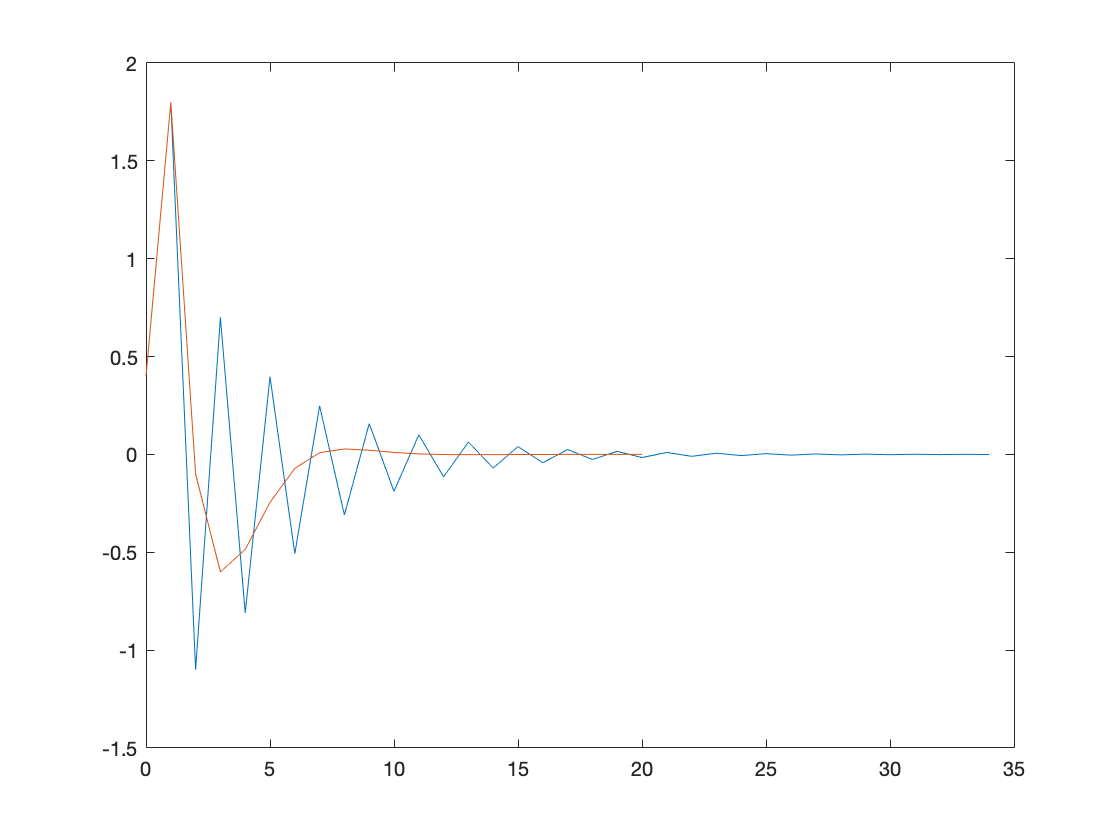

plot(T,Y)